cd 'C:\GitHub\CVUT-MatLab\BnB'
clear;clc;addpath('../Resources/Truss');startup;

Toolbox "yalmip:R20230609:all" added to the Matlab path.

The MATLAB interface for Gurobi 10.0.3 has been installed.

The directory
    C:\Program Files\MATLAB\Gurobi\win64\matlab\
has been added to the MATLAB path.
To use Gurobi regularly, you must save this new path definition.
To do this, type the command
    savepath
at the MATLAB prompt. Please consult the MATLAB documentation
if necessary.


## Ground structure

### Nodes

nodes.x = [0; 1; 2; 0; 1; 2];                       % x coordinates of nodes
nodes.y = [0; 0; 0; 1; 1; 1];                       % y coordinates of nodes
nodes.z = [0; 0; 0; 0; 0; 0];                       % z coordinates of nodes
nnodes  = numel(nodes.x);                           % number of nodes

### Elements

elements.nodes1 = [1; 1; 2; 2; 2; 2; 3; 3; 4; 5];   % elements starting nodes
elements.nodes2 = [2; 5; 3; 4; 5; 6; 5; 6; 5; 6];   % elements ending nodes
nelem = numel(elements.nodes1);  % number of elements  

### Material and cross-section

elements.E = 1.0*ones(nelem, 1);    % Young moduli of individual elements

### Code numbers

## Boundary conditions

### Restricted displacements

kinematic.x.nodes = [1; 4];             % node indices with restricted x-direction displacements
kinematic.y.nodes = [1; 4];             % node indices with restricted y-direction displacements
kinematic.z.nodes = [1;2;3;4;5;6];      % node indices with restricted z-direction displacements

### Load

loads.x.nodes = [];             % node indices with x-direction forces
loads.x.value = [];             % magnitude of the x-direction forces
loads.y.nodes = [2;3];          % node indices with y-direction forces
loads.y.value = [1;1];          % magnitude of the y-direction forces 
loads.z.nodes = [];             % node indices with z-direction forces
loads.z.value = [];             % magnitude of the z-direction forces 

### Boundary conditions

dofs = true(nnodes,3);                % no kinematic boundary conditions
dofs(kinematic.x.nodes,1) = false;    % mark prevented movement in x-direction
dofs(kinematic.y.nodes,2) = false;    % mark prevented movement in y-direction
dofs(kinematic.z.nodes,3) = false;    % mark prevented movement in z-direction

## Optimization parameters

V = 1;                                  % upper bound for the material volume
minimumCrossSectionArea = 1e-6;         % lower bound for cross-section areas. We need it to avoid singular stiffness matrix

## FEM

deltaX = nodes.x(elements.nodes2) - nodes.x(elements.nodes1);
deltaY = nodes.y(elements.nodes2) - nodes.y(elements.nodes1);
deltaZ = nodes.z(elements.nodes2) - nodes.z(elements.nodes1);
lengths = sqrt(deltaX.^2 + deltaY.^2 + deltaZ.^2);
cosinus = [deltaX./lengths deltaY./lengths deltaZ./lengths]

cosinus =     1.0000         0         0
    0.7071    0.7071         0
    1.0000         0         0
   -0.7071    0.7071         0
         0    1.0000         0
    0.7071    0.7071         0
   -0.7071    0.7071         0
         0    1.0000         0
    1.0000         0         0
    1.0000         0         0


### Code numbers

codeNumbers = codeNumbsFn(elements.nodes1,elements.nodes2,nelem,dofs)

codeNumbers =      0     0     0     1     2     0
     0     0     0     5     6     0
     1     2     0     3     4     0
     1     2     0     0     0     0
     1     2     0     5     6     0
     1     2     0     7     8     0
     3     4     0     5     6     0
     3     4     0     7     8     0
     0     0     0     5     6     0
     5     6     0     7     8     0


### Design variables

crossSections = sdpvar(nelem,1);
displacements = sdpvar(nnz(dofs),1);   

### Stifness matrix

stiffnessMatrix = stiffnessMatrixTrussFn(crossSections,elements.E,lengths,cosinus,nelem,codeNumbers);
% v budoucnu lepší způsob skládání matice tuhosti bez for cyklů

### Force vector

forceVector = sparse([loads.x.nodes*3-2; loads.y.nodes*3-1; loads.z.nodes*3], ...
                     1, ...
                     [loads.x.value; loads.y.value; loads.z.value ], ...
                     nnodes*3, 1);
endForces = forceVector(reshape(dofs.', 1, [])');

## Optimization problem formulation and solution

### Constraint 1: volume

volume = lengths'*crossSections <= V;

### Constraint 2: equilibrium equation

equilibriumEquation = stiffnessMatrix*displacements == endForces

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                           Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Equality constraint (bilinear) 8x1|        0.35355 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++


### Constraint 3: lower bound for cross-section areas

nonnegativeCrossSections = crossSections>=minimumCrossSectionArea

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                     Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality 10x1|          1e-06 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++


### Objective function

compliance = endForces'*displacements;

### Solution

ops = sdpsettings('solver','fmincon','verbose',1,'debug',1);
optimize([nonnegativeCrossSections, volume, equilibriumEquation], ...
          compliance, ops);

Your initial point x0 is not between bounds lb and ub; FMINCON
shifted x0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    0.000000e+00    1.054e+01    7.461e-14
    1       2    1.451466e+01    8.968e-01    3.849e+00    1.592e+01
    2       3    1.637390e+01    8.598e-01    3.958e+00    1.900e+00
    3       5    1.653338e+01    8.581e-01    3.878e+00    2.092e-01
    4       7    1.669892e+01    8.590e-01    3.868e+00    1.746e-01
    5       8    1.782330e+01    8.546e-01    4.079e+00    9.473e-01
    6       9    2.182895e+01    8.041e-01    5.181e+00    3.801e+00
    7      10    2.678101e+01    7.361e-01    5.646e+00    5.748e+00
    8      12    4.467845e+01    6.497e-01    7.762e+00    1.970e+01
    9      13    5.811425e+01    4.695e-01    9.890e+00    1.575e+01
   10      14    1.041638e+02    2.653e-01    1.675e+01    5.316e+01
   11    

## Post-procesing

### Write solution

fprintf('Optimized objective: %f\n', value(compliance));

Optimized objective: 121.000340


fprintf('A%d = %f\n', [(1:numel(crossSections))', value(crossSections)]');

A1 = 0.181818
A2 = 0.128564
A3 = 0.090908
A4 = 0.128565
A5 = 0.000001
A6 = 0.000001
A7 = 0.128564
A8 = 0.000001
A9 = 0.181817
A10 = 0.000001


### Plotting

Plot the optimal design. Note that the dimensions are scaled.

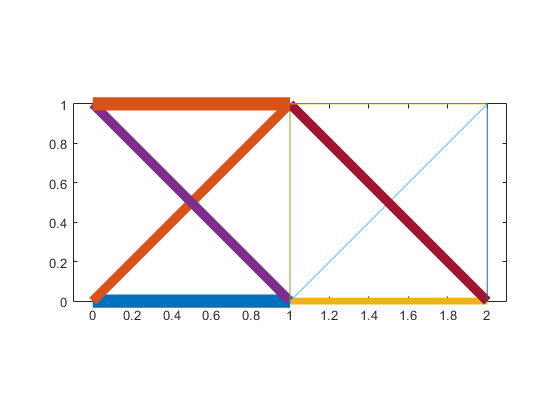

nonzeroAreas = value(crossSections)>minimumCrossSectionArea;
p = plot([nodes.x(elements.nodes1(nonzeroAreas)) nodes.x(elements.nodes2(nonzeroAreas))]',...
         [nodes.y(elements.nodes1(nonzeroAreas)) nodes.y(elements.nodes2(nonzeroAreas))]');
set(p, {'LineWidth'}, num2cell(10*value(crossSections(nonzeroAreas))/max(value(crossSections))));
xlim([min(nodes.x)-0.1,max(nodes.x)+0.1]);  % To avoid tight limits
ylim([min(nodes.y)-0.1,max(nodes.y)+0.1]);  % To avoid tight limits
zlim([min(nodes.z)-0.1,max(nodes.z)+0.1]);  % To avoid tight limits
axis equal